# Attacking Learn++.NSE

In this notebook we will be attacking Learn++.NSE. 

The types of attacks are

- Create a model to predict the future locations of cluster centroids using SINDy. From the predicted clusters at timestep $t$, use AdvLearn to generate attack points. Insert those attack points into the training data of $t$.

- Create a model to predict the future locations of cluster centroids using SINDy. From the predicted clusters at timestep $t$, randomly select points, flip their labels. Insert those attack points into the training data of $t$.

- Based on the actual clusters from timestep $t_{\text{past}}$ generate attack points using AdvLearn. Insert those attack points into the training data of current time step. 

For all attacks we are assuming we do not know the labels of the incoming clusters until they have been classified by Learn++.NSE. So to attack a particular timestep, either predict where the clusters will be and generate attack points accordingly. Alternatively, we could generate attacks based on the clusters of previous timesteps. 

pathsForCode();
close all
clc
DataSet = "X2CDT_FastMovingx8";
Kernel = "Linear";
lambda = 8e-3;
polyOrder = 1;
useSine = 0;
sineMultiplier = 10;
useExp = 0;
expMultiplier = 10;
maxSteps = 150; %250
stepSize = 10; %5
degree = 3;
coef0 = 1;
c = 2; % Class to attack
numAtkPts = 40;
timeStepsInPastToAttack = 4;

[nseData_Baseline,nseResults_Baseline,...
	   ~,~,~,~] = ...
	   LearnPlusPLusNSE_Baseline(DataSet,... % General setting
                                     Kernel);

[NseResults.AdvLearnSINDy,PlottingInfo.AdvLearnSINDy] = ...
AttackingLearnPlusPlusDotNSE(DataSet,"PredictiveOptimized",Kernel,...
                             "Lambda",lambda,"PolyOrder",polyOrder,...
                             "MaxSteps",maxSteps,"StepSize",stepSize,...
                             "Degree",degree,"Coef0",coef0,...
                             "ClassToAttack",c,"NumAttackPoints",numAtkPts,...
                             "TimeStepsInPastToAttack",timeStepsInPastToAttack,...
                             "ReturnPlottingInfo",1,"MeasureSINDyResults",1);
                         
[NseResults.AdvLearn,PlottingInfo.AdvLearn] = ...
AttackingLearnPlusPlusDotNSE(DataSet,"NonPredictiveOptimized",Kernel,...
                             "MaxSteps",maxSteps,"StepSize",stepSize,...
                             "Degree",degree,"Coef0",coef0,...
                             "ClassToAttack",c,"NumAttackPoints",numAtkPts,...
                             "TimeStepsInPastToAttack",timeStepsInPastToAttack,...
                             "ReturnPlottingInfo",1);                             
                         


## Results

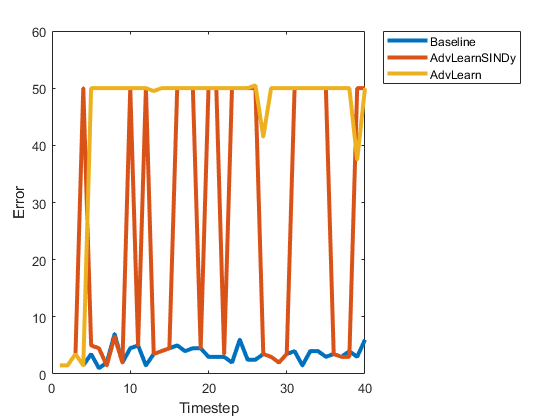

AdvLearnError = [NseResults.AdvLearn.Error];
AdvLearnSINDyError = [NseResults.AdvLearnSINDy.Error];
BaselineError = [nseResults_Baseline(1:40).errs_nse];

Error(1,:) = BaselineError;
Error(2,:) = AdvLearnSINDyError;
Error(3,:) = AdvLearnError;
figure
plot((1:40)',Error'*100,'LineWidth',3)
xlabel('Timestep')
ylabel('Error')
legend('Baseline','AdvLearnSINDy','AdvLearn','Location','bestoutside')

### AdvLearn With SINDy 

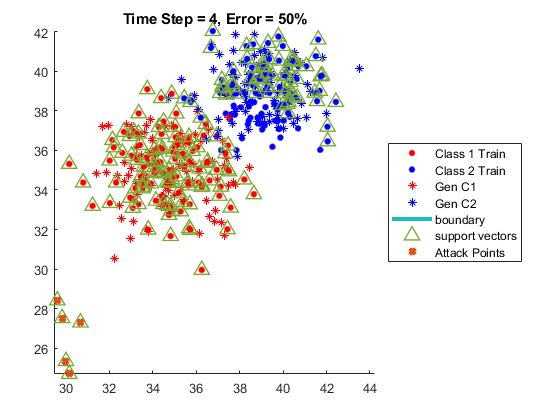

timeStep = 4;
svmNumber = 1;
svmMatch = true;
plotGenData = true;
plotPrevdata = true;
plotResultsAdvLearnSINDy(PlottingInfo.AdvLearnSINDy.GenDistr,PlottingInfo.AdvLearnSINDy.AtkData,NseResults.AdvLearnSINDy,timeStep,svmNumber,svmMatch,PlottingInfo.AdvLearnSINDy.NseData,plotGenData)

### AdvLearn

% plotResultsAdvLearn(atkData_AdvLearn,nseResults_AdvLearn,timeStep,svmNumber,svmMatch,nseData_AdvLearn,timeStepsInPastToAttack,plotPrevdata)